# Question 3

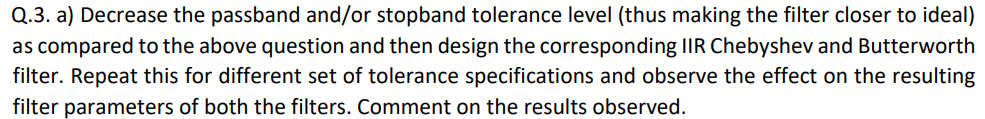

Sampling_Frequency = 2000;
Pass_Band_frequency  = 100;
Stop_band_frequency = 500;  
Pass_Band_attenuation = -0.1;    
Stop_Band_attenuation = -100;

## Part 1: changing the tolerance

Pass_Band_analysis = [-4,-2,-1,-0.8,-0.4,-0.1];

### Chebyshev

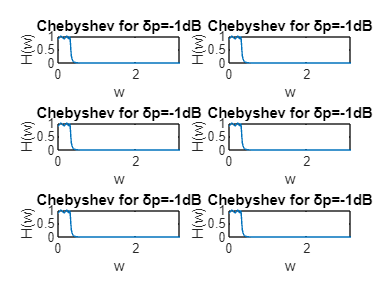

clf
for i= 1:6
Pass_Band_attenuation = Pass_Band_analysis(i);
[n1,wn1] = cheb1ord(2*Pass_Band_frequency/Sampling_Frequency,2*Stop_band_frequency/Sampling_Frequency,-Pass_Band_attenuation,-Stop_Band_attenuation);
[a1,b1] = cheby1(n1,-Pass_Band_attenuation,wn1);

w1 = 0:0.01:pi;
Hw1 = freqz(a1,b1,w1);

subplot(3,2,i)
plot(w1,abs(Hw1))
title(['Chebyshev for δp=',num2str(Pass_Band_attenuation),'dB'])
ylabel('H(w)')
xlabel('w')
end

### ButterWorth

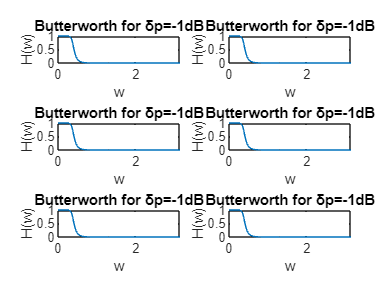

clf
for i= 1:6
Pass_Band_attenuation = Pass_Band_analysis(i);
[n2,wn2] = buttord(2*Pass_Band_frequency/Sampling_Frequency,2*Stop_band_frequency/Sampling_Frequency,-Pass_Band_attenuation,-Stop_Band_attenuation);
[a2,b2] = butter(n2,wn2);

w2 = 0:0.01:pi;
Hw2 = freqz(a2,b2,w2);

subplot(3,2,i)
plot(w2,abs(Hw2))
title(['Butterworth for δp=',num2str(Pass_Band_attenuation),'dB'])
ylabel('H(w)')
xlabel('w')
end

## Part 2: changing the bandwidth using Wn

Pass_Band_attenuation=-1;
bandwidths = [0.5,0.3,0.1,0.05,0.02,0.01];

### Chebyshev

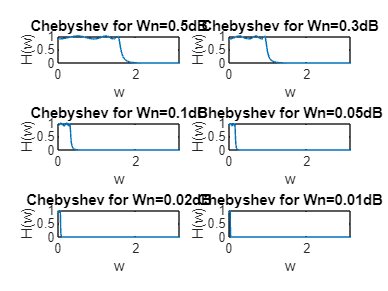

clf
for i= 1:6
[a1,b1] = cheby1(n1,-Pass_Band_attenuation,bandwidths(i));

w1 = 0:0.01:pi;
Hw1 = freqz(a1,b1,w1);

subplot(3,2,i)
plot(w1,abs(Hw1))
title(['Chebyshev for Wn=',num2str(bandwidths(i)),'dB'])
ylabel('H(w)')
xlabel('w')
end

### ButterWorth

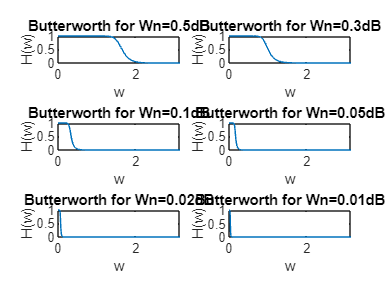

clf
for i= 1:6
[n2,wn2] = buttord(2*Pass_Band_frequency/Sampling_Frequency,2*Stop_band_frequency/Sampling_Frequency,-Pass_Band_attenuation,-Stop_Band_attenuation);
[a2,b2] = butter(n2,bandwidths(i));

w2 = 0:0.01:pi;
Hw2 = freqz(a2,b2,w2);

subplot(3,2,i)
plot(w2,abs(Hw2))
title(['Butterworth for Wn=',num2str(bandwidths(i)),'dB'])
ylabel('H(w)')
xlabel('w')
end

## Part 3: Changing both tolerance and bandwidth

### Chebyshev

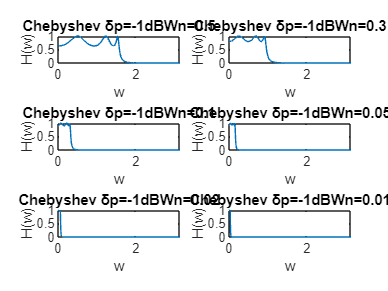

for i = 1:6
[a1,b1] = cheby1(n1,-Pass_Band_analysis(i),bandwidths(i));

w1 = 0:0.01:pi;
Hw1 = freqz(a1,b1,w1);

subplot(3,2,i)
plot(w1,abs(Hw1))
title(['Chebyshev δp=',num2str(Pass_Band_attenuation),'dB','Wn=',num2str(bandwidths(i))])
ylabel('H(w)')
xlabel('w')
end

## Butterworth

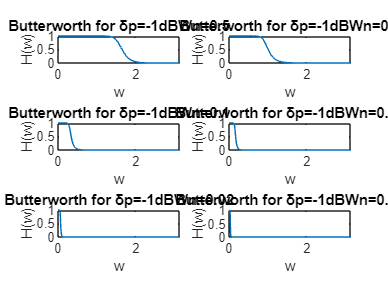

for i=1:6
[n2,wn2] = buttord(2*Pass_Band_frequency/Sampling_Frequency,2*Stop_band_frequency/Sampling_Frequency,-Pass_Band_analysis(i),-Stop_Band_attenuation);
[a2,b2] = butter(n2,bandwidths(i));

w2 = 0:0.01:pi;
Hw2 = freqz(a2,b2,w2);

subplot(3,2,i)
plot(w2,abs(Hw2))
title(['Butterworth for δp=',num2str(Pass_Band_attenuation),'dB','Wn=',num2str(bandwidths(i))])
ylabel('H(w)')
xlabel('w')
end